I_init = 1;
I_end = 0;
I_k_mu = 0;
I_k_sigma = 0;

E_init = 0;
E_end = 1;
E_k_mu_1 = .482;
E_k_mu_2 = .428;
E_k_sigma = .031;


I_k = I_k_mu + I_k_sigma * randn(100, 1);
E_k_1 = E_k_mu_1 + E_k_sigma * randn(100, 1);
E_k_2 = E_k_mu_2 + E_k_sigma * randn(100, 1);

I_k(I_k>0) = 0;
E_k_1(E_k_1<0) = 0;
E_k_2(E_k_2<0) = 0;

figure(); hold on;
ksdensity(1./E_k_1)
ksdensity(1./E_k_2)

t_response_1 = (I_init - E_init) ./ (E_k_1 - I_k);
t_response_2 = (I_init - E_init) ./ (E_k_2 - I_k);

bins = 0:.001:3;
band_width = 0.12;
n_boot = 1000;
alpha_boot = 0.05;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width); % 
boot_pdf = @(x) bootci(n_boot, {kde_pdf, x}, 'type', 'cper', 'alpha', alpha_boot);


pdf_1 = kde_pdf(t_response_1);
pdf_2 = kde_pdf(t_response_2);

pdf_1_ci = boot_pdf(t_response_1);
pdf_2_ci = boot_pdf(t_response_2);


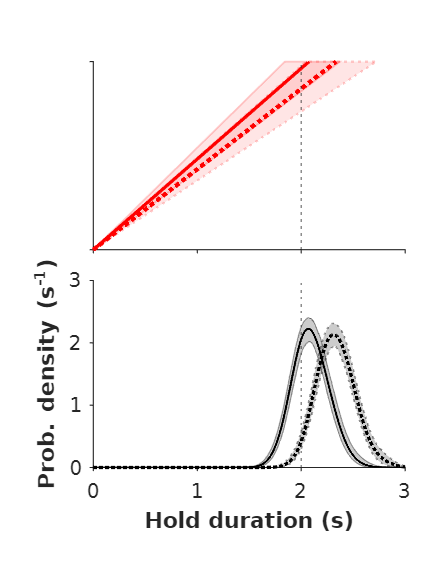

fig = figure(70); clf(fig);
set(fig, 'Color', 'w', 'Units', 'centimeters', 'Position', [5 5 7 9]);

%
ax_mdl = axes(fig);
set(ax_mdl, 'Units', 'centimeters', 'Position', [1.5 5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_mdl, 2, 'LineWidth', .5, 'LineStyle', ':');

fill(ax_mdl, [0 (I_end-I_init)/(I_k_mu+1.96*I_k_sigma) (I_end-I_init)/(I_k_mu-1.96*I_k_sigma)], [I_init I_end I_end], 'b', ...
    'FaceAlpha', .1, 'EdgeColor', 'b', 'EdgeAlpha', .2, ...
    'LineStyle', '-', 'LineWidth', .8);
plot(ax_mdl, [0 (I_end-I_init)/I_k_mu], [I_init I_end], 'Color', 'b', 'LineWidth', 1.5);

fill(ax_mdl, [0 (E_end-E_init)/(E_k_mu_1+1.96*E_k_sigma) (E_end-E_init)/(E_k_mu_1-1.96*E_k_sigma)], [E_init E_end E_end], 'r', ...
    'FaceAlpha', .1, 'EdgeColor', 'r', 'EdgeAlpha', .2, ...
    'LineStyle', '-', 'LineWidth', .8);
plot(ax_mdl, [0 (E_end-E_init)/E_k_mu_1], [E_init E_end], 'Color', 'r', 'LineWidth', 1.5);

fill(ax_mdl, [0 (E_end-E_init)/(E_k_mu_2+1.96*E_k_sigma) (E_end-E_init)/(E_k_mu_2-1.96*E_k_sigma)], [E_init E_end E_end], 'r', ...
    'FaceAlpha', .1, 'EdgeColor', 'r', 'EdgeAlpha', .2, ...
    'LineStyle', ':', 'LineWidth', 1);
plot(ax_mdl, [0 (E_end-E_init)/E_k_mu_2], [E_init E_end], 'Color', 'r', 'LineWidth', 2, 'LineStyle', ':');

set(ax_mdl, 'XLim', [0 3], 'YLim', [0 1], 'XTickLabel', [], 'YTickLabel', [], 'YTick', [E_init I_init]);

%
ax_rt = axes(fig);
set(ax_rt, 'Units', 'centimeters', 'Position', [1.5 1.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_rt, 2, 'LineWidth', .5, 'LineStyle', ':');
fill(ax_rt, [bins flip(bins)], [pdf_1_ci(1,:) flip(pdf_1_ci(2,:))], 'y', ...
    'FaceColor', 'k', 'FaceAlpha', .2, ...
    'EdgeColor', 'k', 'EdgeAlpha', .4, ...
    'LineStyle', '-', 'LineWidth', .5);
plot(ax_rt, bins, pdf_1, ...
    'color', 'k', 'linewidth', 1, 'LineStyle', '-');
fill(ax_rt, [bins flip(bins)], [pdf_2_ci(1,:) flip(pdf_2_ci(2,:))], 'y', ...
    'FaceColor', 'k', 'FaceAlpha', .2, ...
    'EdgeColor', 'k', 'EdgeAlpha', .4, ...
    'LineStyle', ':', 'LineWidth', .8);
plot(ax_rt, bins, pdf_2, ...
    'color', 'k', 'linewidth', 1.5, 'LineStyle', ':');

ax_rt.YLabel.String = "Prob. density (s^{-1})";
ax_rt.YLabel.FontWeight = "bold";
ax_rt.XLabel.String = "Hold duration (s)";
ax_rt.XLabel.FontWeight = "bold";

set(ax_rt, 'XLim', [0 3]);